# The application of Logical relationship calculation

clear;
clc;

t = -5*pi:pi/10:5*pi;    % independent variable t, contains 0.
y = sin(t)./t;           % at the position t = 0, it will produce NaN, according to IEEE rule.

tt = t + (t==0)*eps;     % replace the 0 with a "machine zero : epsilon".

Because the limitation : $\lim_{x\to 0} \frac{sin\left(x\right)}{x}=1$, we will replace the limitation calculation with $\frac{sin\left(\varepsilon \right)}{\varepsilon }$ at the position $x=0$

$epsilon:\varepsilon$ is the least minimal number in the computer $\varepsilon =2\ldotp 2204\text{ }\times \text{ }{10}^{−16}$

yy = sin(tt)./tt;


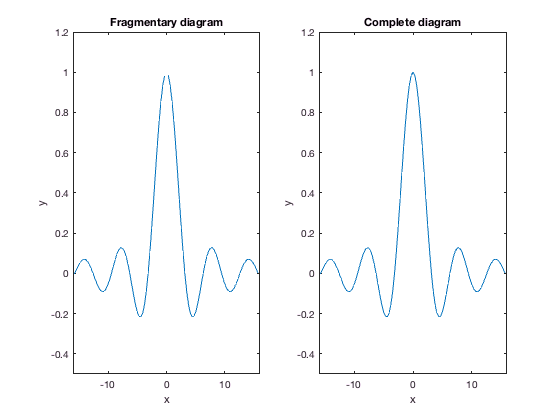

% Plot the 2 diagrams as below :
subplot(1, 2, 1);
plot(t, y);
axis([-16, 16, -0.5, 1.2]);
xlabel('x');
ylabel('y');
title('Fragmentary diagram');

subplot(1, 2, 2);
plot(tt, yy);
axis([-16, 16, -0.5, 1.2]);
xlabel('x');
ylabel('y');
title('Complete diagram');